**Adrian Cristian Crisan**

[https://drive.matlab.com/sharing/193e6ea3-d938-48aa-97dc-55fa6ab04c04](https://drive.matlab.com/sharing/193e6ea3-d938-48aa-97dc-55fa6ab04c04)

# Forward Kinematics TODO

#### 1) Derive the DH-Std parameters and the neighbouring homogeneous transformation  matrices , for i=1,2,3, as functions of the joint angles. Draw the joint frames.

clear
mdl_3link3d
R3

 
R3 = 
 
3link 3D (3 axis, RRR, stdDH, fastRNE)                           
 Spong p106;                                                     
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          1|          0|      1.571|          0|
|  2|         q2|          0|          2|          0|          0|
|  3|         q3|          0|          3|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1              
 


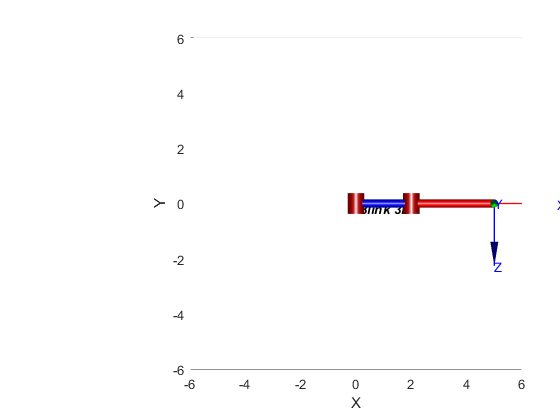

R3.plot([0 0 0])        % Mueve el brazo
R3.teach

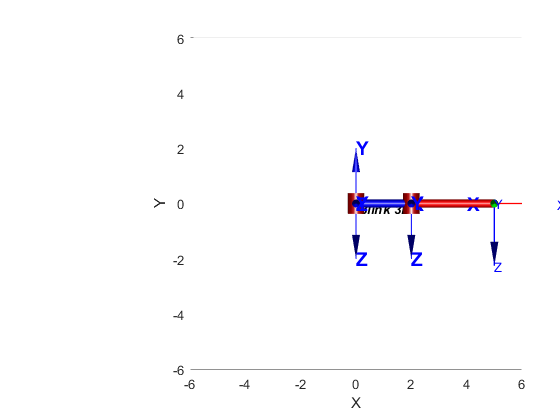

T4 = eye(4);
T3_4 = T4 * link_A_B_Std(R3.links(1).alpha, R3.links(1).a, R3.links(1).d, R3.links(1).theta);
T2_3 = T3_4 * link_A_B_Std(R3.links(2).alpha, R3.links(2).a, R3.links(2).d, R3.links(2).theta);
T1_2 = T2_3 * link_A_B_Std(R3.links(3).alpha, R3.links(3).a, R3.links(3).d, R3.links(3).theta);

hold on
trplot(T4, 'length', 2, 'arrow', 'width', 0.5, 'color','b', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
trplot(T3_4, 'length', 2, 'arrow', 'width', 0.5, 'color','b', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
trplot(T2_3, 'length', 2, 'arrow', 'width', 0.5, 'color','b', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
hold off


% Already represented
% trplot(T1, 'length', 2, 'arrow', 'width', 0.5, 'color','b', ...
%              'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})

#### 3) Calculate the result for the following joint angles: (0, 0, 0), (0, π/2, 0), and (0,  π/2, π/6).

(0, 0, 0)

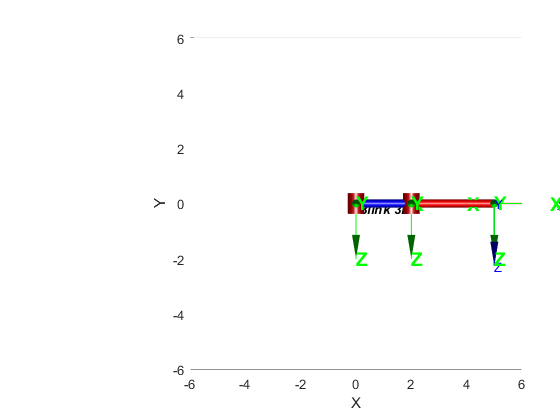

clf
R3.teach
hold on
T3_4_fw1 = T3_4 * trotz(0);
T2_3_fw2 = T2_3 * trotz(0);
T1_2_fw3 = T1_2 * trotz(0);

trplot(T3_4_fw1, 'length', 2, 'arrow', 'width', 0.5, 'color','g', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
trplot(T2_3_fw2, 'length', 2, 'arrow', 'width', 0.5, 'color','g', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
trplot(T1_2_fw3, 'length', 2, 'arrow', 'width', 0.5, 'color','g', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})

(0, π/2, 0)

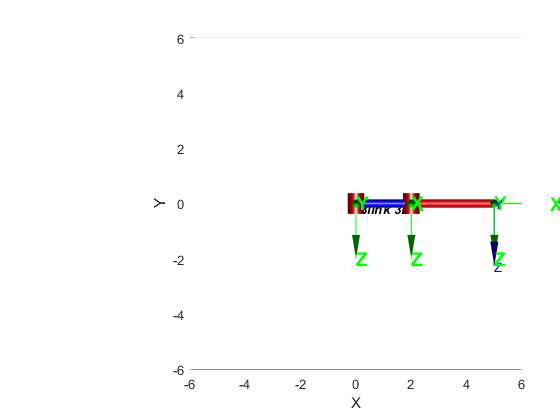

clf
R3.teach
hold on
T3_4_fw1 = T3_4 * trotz(0);
T2_3_fw2 = T2_3 * trotz(pi/2);
T1_2_fw3 = T1_2 * trotz(0);

trplot(T3_4_fw1, 'length', 2, 'arrow', 'width', 0.5, 'color','g', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
trplot(T2_3_fw2, 'length', 2, 'arrow', 'width', 0.5, 'color','g', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
trplot(T1_2_fw3, 'length', 2, 'arrow', 'width', 0.5, 'color','g', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})

(0,  π/2, π/6)

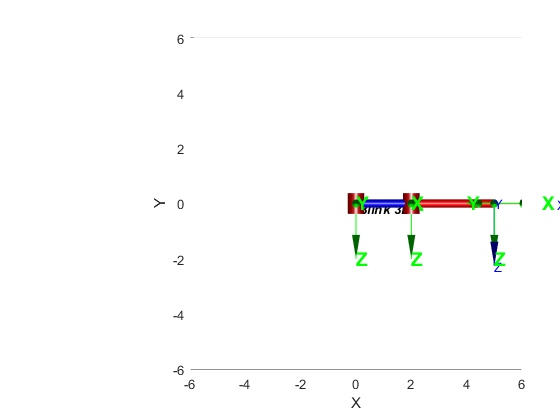

clf
R3.teach
hold on
T3_4_fw1 = T3_4 * trotz(0);
T2_3_fw2 = T2_3 * trotz(pi/2);
T1_2_fw3 = T1_2 * trotz(pi/6);

trplot(T3_4_fw1, 'length', 2, 'arrow', 'width', 0.5, 'color','g', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
trplot(T2_3_fw2, 'length', 2, 'arrow', 'width', 0.5, 'color','g', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})
trplot(T1_2_fw3, 'length', 2, 'arrow', 'width', 0.5, 'color','g', ...
             'text_opts', {'FontSize', 14, 'FontWeight', 'bold'})

## Functions in the mlx

Put at the end all specific function that clarify the code.

function T_b_a=link_A_B_Std(alpha,a,d,theta)
T_b_a=trotz(theta)*transl(0,0,d)*transl(a,0,0)*trotx(alpha);
end